Ebad Syed

1270329

# EENG 860 Special Topics: Digital Image Processing Project 2


% load degradation object
load BlurKernels.mat;

%load image and normalize to [0 1]
cameraMan_original = mat2gray(imread("cameraman.tif"));

house_original = mat2gray(imread("house.tif"));
house_original = house_original(:,:,1); %we dont need the second array

mandril_original = mat2gray(imread("mandril_gray.tif"));

% Add the blur to images

cameraMan_blur = blur_Image(cameraMan_original,gaussianBlurKernel,linearMotionBlurKernel,nonLinearMotionBlurKernel);
house_blur = blur_Image(house_original,gaussianBlurKernel,linearMotionBlurKernel,nonLinearMotionBlurKernel);
mandril_blur = blur_Image(mandril_original,gaussianBlurKernel,linearMotionBlurKernel,nonLinearMotionBlurKernel);

% Add noise with 0 mean and 0.1% Variance 

noise_mean = 0;
noise_var = 0.01;

cameraMan_blur_noise = imnoise(cameraMan_blur,'gaussian',noise_mean,noise_var);
house_blur_noise = imnoise(house_blur,'gaussian',noise_mean,noise_var);
mandril_blur_noise = imnoise(mandril_blur,'gaussian',noise_mean,noise_var);

% Testing the Filters only on CameraMan Images in this code

% Restored Images using Inverse Fiter

cameraMan_gaussian_restored_inv = inverse_filter(cameraMan_blur_noise(:,:,1),gaussianBlurKernel,0.4);
cameraMan_linear_restored_inv = inverse_filter(cameraMan_blur_noise(:,:,2),linearMotionBlurKernel,0.4);
cameraMan_nonlinear_restored_inv = inverse_filter(cameraMan_blur_noise(:,:,3),nonLinearMotionBlurKernel,0.3);

% Restored Images using Wiener Filter

% Estimating NSR for K for Wiener Filter
signal_var = var(cameraMan_original(:)); %Signal Variance
NSR = noise_var / signal_var; % Noise to Signal Ratio

cameraMan_gaussian_restored_wnr = wnr_filter(cameraMan_blur_noise(:,:,1),gaussianBlurKernel,NSR);
cameraMan_linear_restored_wnr = wnr_filter(cameraMan_blur_noise(:,:,2),linearMotionBlurKernel,NSR);
cameraMan_nonlinear_restored_wnr = wnr_filter(cameraMan_blur_noise(:,:,3),nonLinearMotionBlurKernel,NSR);

% Restored Images using CLSF Filter

% We use Noise Power to estimate the Laplacian
% Estimating Noise Power 
NP = noise_var*numel(cameraMan_original);

cameraMan_gaussian_restored_clsf = clsf_filter(cameraMan_blur_noise(:,:,1),gaussianBlurKernel,NP);
cameraMan_linear_restored_clsf = clsf_filter(cameraMan_blur_noise(:,:,2),linearMotionBlurKernel,NP);
cameraMan_nonlinear_restored_clsf = clsf_filter(cameraMan_blur_noise(:,:,3),nonLinearMotionBlurKernel,NP);


## RESULTS

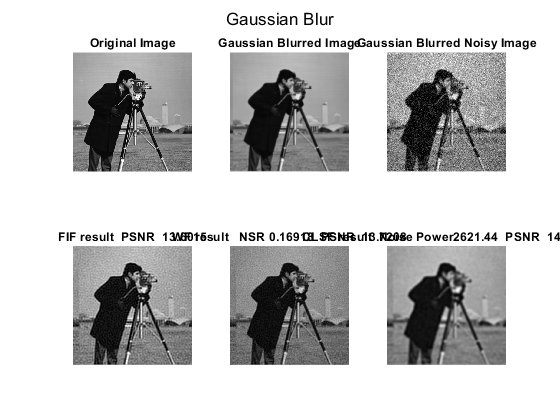


figure;
sgtitle('Gaussian Blur')
subplot(2,3,1),imshow(cameraMan_original),title('Original Image')
subplot(2,3,2),imshow(cameraMan_blur(:,:,1)),title('Gaussian Blurred Image')
subplot(2,3,3),imshow(cameraMan_blur_noise(:,:,1)),title('Gaussian Blurred Noisy Image')
subplot(2,3,4),imshow(cameraMan_gaussian_restored_inv),title(['FIF result', '  PSNR  ',num2str(psnr(cameraMan_original,cameraMan_gaussian_restored_inv,1))])
subplot(2,3,5),imshow(cameraMan_gaussian_restored_wnr),title(['WF result','   NSR ',num2str(NSR), '  PSNR  ',num2str(psnr(cameraMan_original,cameraMan_gaussian_restored_wnr,1))])
subplot(2,3,6),imshow(cameraMan_gaussian_restored_clsf),title(['CLSF result','  Noise Power',num2str(NP), '  PSNR  ',num2str(psnr(cameraMan_original,cameraMan_gaussian_restored_clsf,1))])

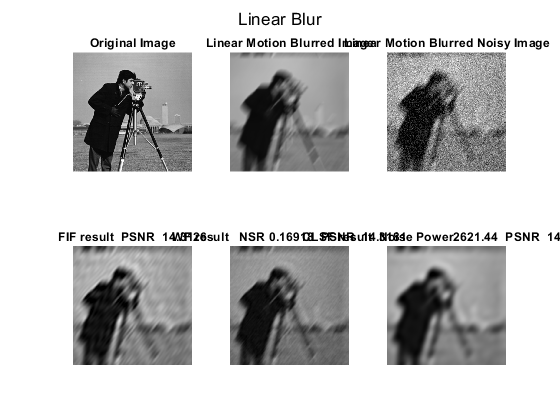

figure;
sgtitle('Linear Blur')
subplot(2,3,1),imshow(cameraMan_original),title('Original Image')
subplot(2,3,2),imshow(cameraMan_blur(:,:,2)),title('Linear Motion Blurred Image')
subplot(2,3,3),imshow(cameraMan_blur_noise(:,:,2)),title('Linear Motion Blurred Noisy Image')
subplot(2,3,4),imshow(cameraMan_linear_restored_inv),title(['FIF result', '  PSNR  ',num2str(psnr(cameraMan_original,cameraMan_linear_restored_inv,1))])
subplot(2,3,5),imshow(cameraMan_linear_restored_wnr),title(['WF result','   NSR ',num2str(NSR), '  PSNR  ',num2str(psnr(cameraMan_original,cameraMan_linear_restored_wnr,1))])
subplot(2,3,6),imshow(cameraMan_linear_restored_clsf),title(['CLSF result','  Noise Power',num2str(NP), '  PSNR  ',num2str(psnr(cameraMan_original,cameraMan_linear_restored_clsf,1))])

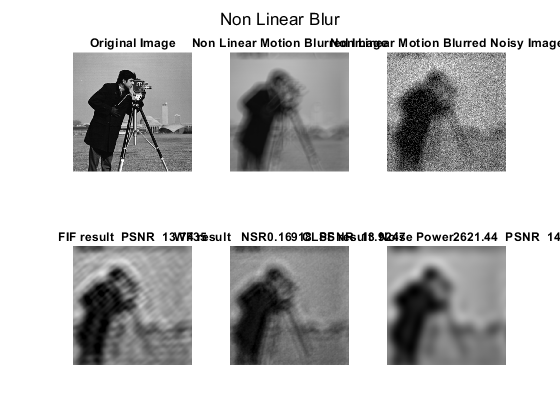


figure;
sgtitle('Non Linear Blur')
subplot(2,3,1),imshow(cameraMan_original),title('Original Image')
subplot(2,3,2),imshow(cameraMan_blur(:,:,3)),title('Non Linear Motion Blurred Image')
subplot(2,3,3),imshow(cameraMan_blur_noise(:,:,3)),title('Non Linear Motion Blurred Noisy Image')
subplot(2,3,4),imshow(cameraMan_nonlinear_restored_inv),title(['FIF result', '  PSNR  ',num2str(psnr(cameraMan_original,cameraMan_nonlinear_restored_inv,1))])
subplot(2,3,5),imshow(cameraMan_nonlinear_restored_wnr),title(['WF result','   NSR',num2str(NSR), '  PSNR  ',num2str(psnr(cameraMan_original,cameraMan_nonlinear_restored_wnr,1))])
subplot(2,3,6),imshow(cameraMan_nonlinear_restored_clsf),title(['CLSF result','  Noise Power',num2str(NP), '  PSNR  ',num2str(psnr(cameraMan_original,cameraMan_nonlinear_restored_clsf,1))])

## Filter Inverse Filter

The filter inverse filter has been implemented by writing the algorithm on its own. Various value of Do has been tested.

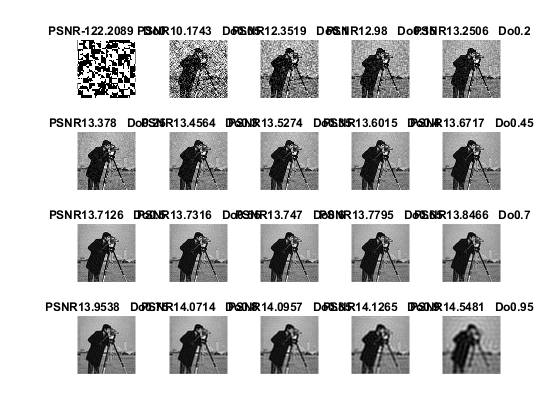

openfig("PSNR_Gaussian_InverseFilter.fig");

From this we can verify that increasing the value of Do increases the PSNR, however, the the picture loses the sharpness and becomes increasingly smooth i.e less details. Therefore an intermediate value of Do is selected for results which shows images with more details.

## Wiener Filtering

The filter has been implemented using the 'deconvwnr', function of MATLAB. To estimate the correct value of K we have used Noise to Signal Ratio.

## CLSF Filtering

The filter has been implemented using the 'deconvreg'; function of MATLAB. To estimate the correct value of Laplacian the algorithm needs the noise power which has been calculated and entered.

## Conclusion

From the results we can observe that Wiener Filter has been generally better at Restoring the Images. Despite the fact that CLSF filter has higher PSNR Values. However, the details are also lost in CLSF and aesthetically images with Wiener Filter are much better.